clear all;
close all;
clc;


## part 1



A = [-0.127 -235 -32.2 -9.51 0.314;-7E-4 -0.969 0 0.908 -2E-4;0 0 0 1 0; 9E-4 -4.56 0 -1.58 0;0 0 0 0 -5];
B = [0 -0.244;0 -0.00209; 0 0;10 -0.199; 1087 0];
C = [0 57.3 0 0 0;0 0 0 1 0;0.0208 15.2 0 1.45 0];
D = [0 0;0 0;0 0.033];
Gn = ss(A,B,C,D);

size(Gn)

State-space model with 3 outputs, 2 inputs, and 5 states.




eigenvalues = eig(A);
if all(real(eigenvalues) < 0)
    disp('it is stable');
else
    disp('it is not stable');
end

it is stable



disp(eigenvalues);

  -1.2782 + 1.9687i
  -1.2782 - 1.9687i
  -0.0598 + 0.1420i
  -0.0598 - 0.1420i
  -5.0000 + 0.0000i




% check minimal
controllability_rank = rank(ctrb(A,B));
observability_rank = rank(obsv(A,C));
if controllability_rank == size(A,1) && observability_rank == size(A,1)
    disp('it is minimal');
else
    disp('it is not minimal');
end

it is minimal



disp('controllability_rank');

controllability_rank


disp(controllability_rank);

     5



disp('observability_rank');

observability_rank


disp(observability_rank);

     5



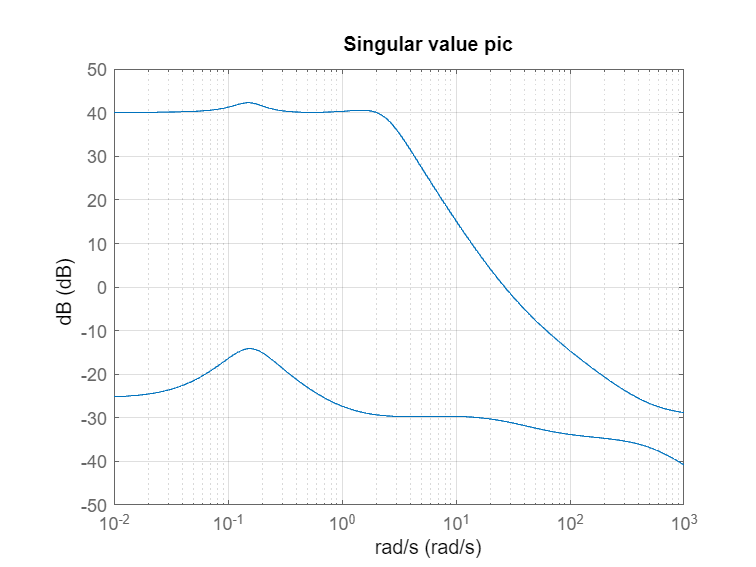



% Singular value
omega = logspace(-2,3,500); % ω ∈ [0.01, 1000]
sigma(Gn,omega);
title('Singular value pic');
xlabel('rad/s');
ylabel('dB');
grid on;


% H_inf and H2
H_inf_norm = norm(Gn,inf);
H_2_norm = norm(Gn,2);

disp(['H_inf : ', num2str(H_inf_norm)]);

H_inf : 130.6905


disp(['H_2 : ', num2str(H_2_norm)]);

H_2 : Inf




[~,~,omega] = svdplot(Gn);

Unrecognized function or variable 'svdplot'.

[~, index] = max(mag(:));
omega_max = omega(index);




## part 2

size(A);
% Define the selection matrix for angle of attack alpha
C2 = [0,1,0,0,0];
% C2 = C(1,:);%Derive later

t = 0:0.1:100;  % Time vectorlen = size(t,2)-1;
len = size(t,2)-1;
r = [zeros(1,0.2*len) 10*ones(1,0.3*len) zeros(1, 0.2*len) ones(1,0.3*len+1)];
r = deg2rad(r);%state is in rad, so need convert

% Extend the state-space model for LQI
A_aug = [A zeros(size(A,1),1); C2 0*eye(1)];
% B_aug = [B,0*eye(1); zeros(1,size(B,2)),eye(1)]; %r-state
% B_aug = [zeros(1,5),-1]'; % the only input is r ,should not use the original one

B_aug = [B zeros(size(A, 1), 1); zeros(1, size(B, 2)) -1];

% Define weight matrices for LQR design
Q_aug = diag([0, 100, 0, 0, 0, 1]);  
R = diag(1);        

% Compute the LQR gain matrix for the augmented system
K_aug = lqr(A_aug, B_aug, Q_aug, R)
disp("The LQI controller is:");
disp(K_aug);
% The control law is u = -K_aug * x_aug


Ae = A_aug - B_aug * K_aug;
Be = B_aug;
Ce = eye(size(A_aug));
De = 0;
sys_e = ss(Ae, Be, Ce, De);

% 
% [y1,t] = step(sys_e);
% 
% y1(:,2) = rad2deg(y1(:,2));
% figure;
% hold on;
% subplot(1,2,1)
% hold on;
% plot(t,y1(:,2));
% plot([min(t) max(t)], [1 1], 'k--');
% legend('state alpha(deg)');
% 
% subplot(1,2,2)
% hold on;
% plot(t,y1(:,6));
% legend('augment state');



ref = [zeros(1,size(r,2));zeros(1,size(r,2));r];
[y, t] = lsim(sys_e, ref, t);

%[V(ft/s) speed, alpha(rad) angle of attack, theta(rad) pitch angle, q(rad/s) pitch rate, T(lb) engine_power]'

% y(:,2) = rad2deg(y(:,2));
figure;
hold on;

subplot(3,1,1)
hold on;
plot(t,r);
legend('ref');

subplot(3,1,2)
hold on;
plot(t,y(:,2));
plot([min(t) max(t)], [1 1], 'k--');
legend('state alpha');

subplot(3,1,3)
hold on;
plot(t,y(:,6));
legend('augment state');


## part3